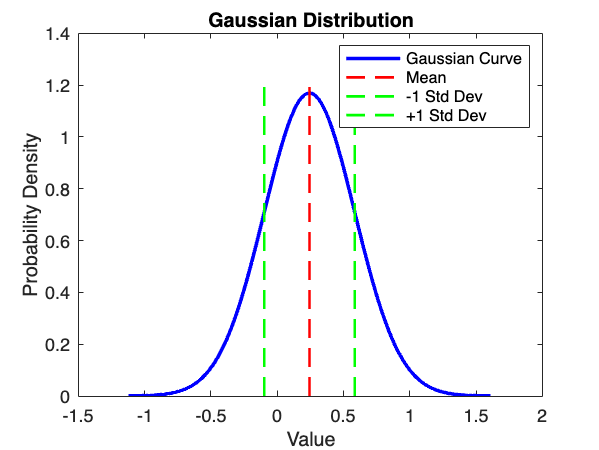

counter = 0;

% disp(counter);
% Calculate mean and standard deviation
mu = mean(results_table.time);
sigma = std(results_table.time);

% Define x range for Gaussian plot (e.g., from mean - 4*std to mean + 4*std)
x = linspace(mu - 4*sigma, mu + 4*sigma, 1000);

% Gaussian distribution
y = (1/(sigma * sqrt(2 * pi))) * exp(-(x - mu).^2 / (2 * sigma^2));

% Plot the Gaussian distribution
figure;
plot(x, y, 'b-', 'LineWidth', 2);
hold on;

% Plot lines for mean and standard deviations
yLimits = ylim; % Get y-axis limits for line plotting
plot([mu, mu], yLimits, 'r--', 'LineWidth', 1.5); % Mean line
plot([mu - sigma, mu - sigma], yLimits, 'g--', 'LineWidth', 1.5); % -1 std dev line
plot([mu + sigma, mu + sigma], yLimits, 'g--', 'LineWidth', 1.5); % +1 std dev line

% Add labels and title
xlabel('Value');
ylabel('Probability Density');
title('Gaussian Distribution');
legend('Gaussian Curve', 'Mean', '-1 Std Dev', '+1 Std Dev');

hold off;